# Toxic Conversations Dataset

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/toxic_conversations_50k/toxic_conversations_50k_all-mpnet-base-v2.parquet", "SelectedVariableNames", ["text", "label_text", "embedding"]);

rawData.label_text = categorical(rawData.label_text);

rawData(1:8, :)

ans = 8×3 table
                                                                                                                                                                                                                                                                                       text                                                                                                                                                                                                                                                                                       label_text      embedding   
    __________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

groupcounts(rawData, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic       46035        92.07 
    toxic            3965         7.93 


## Preperation

sampleSize = 1000;
contamination =0.2;
nonToxicIndices = find(rawData.label_text == "not toxic");
toxicIndices = find(rawData.label_text == "toxic");

numToxicSamples = round(contamination * sampleSize);
numNonToxicSamples = sampleSize - numToxicSamples;

toxicSampleIndices = datasample(toxicIndices, numToxicSamples, Replace=false);
nonToxicSampleIndices = datasample(nonToxicIndices, numNonToxicSamples, Replace=false);
data = rawData(sort(cat(1, toxicSampleIndices, nonToxicSampleIndices)),:);

clear numToxicSamples;
clear numNonToxicSamples;
clear toxicSampleIndices;
clear toxicIndices;
clear nonToxicIndices;
clear nonToxicSampleIndices;
clear rawData;

groupcounts(data, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic        800          80   
    toxic            200          20   


unlabeledData = cell2mat(cellfun(@transpose,data.embedding, UniformOutput=false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.label_text, {'not toxic' 'toxic'}, {'inlier' 'outlier'});

## Separability

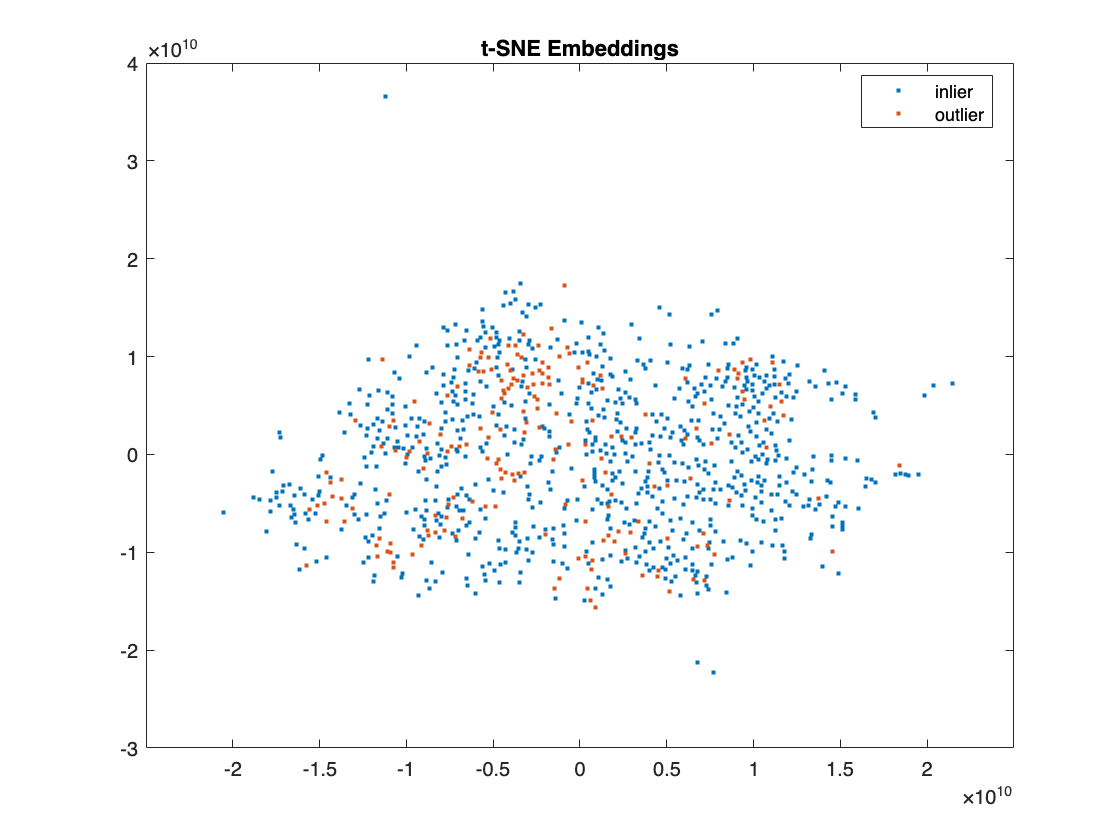

Y = tsne(unlabeledData, Distance="cosine");

figure;
gscatter(Y(:,1),Y(:,2),labels);
title("t-SNE Embeddings");

clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

Unrecognized function or variable 'separabilityindex'.

## Computation

alpha = 0.7;
% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);
poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "label_text")
outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "label_text")

### Confusion Matrix

grouphat = categorical(repmat("inlier", size(labels)), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat);
figure;
confusionchart(cm, categories(labels));
struct2table(confusionstats(cm))

### Mahalanobis Distances

figure;
mahalchart(labels, solution.rd, solution.cutoff);

evaluation(unlabeledData, labels, alpha, solution)

% objectiveplot(poc, centredData);
objectiveplot(poc, unlabeledData);